# Redes Neuronales

# Aprendizaje no Supervisado

# Tarea 9

# Dataset Ds3c3sc6

**Realizado por: **David Fabián Cevallos Salas

**Fecha: **2023-08-29

tic
clc;
clear;
close all;
rng(0);
warning("off","all");

% Carga y limpieza de datos
datos = importdata("ds3.txt");
X = datos(:,1:2);

% ---------------------------------------
% k-means
% ---------------------------------------
fprintf("---------------------------------------")

---------------------------------------

fprintf("k-means")

k-means

fprintf("---------------------------------------")

---------------------------------------


n = 20

n = 20

k = 6

k = 6

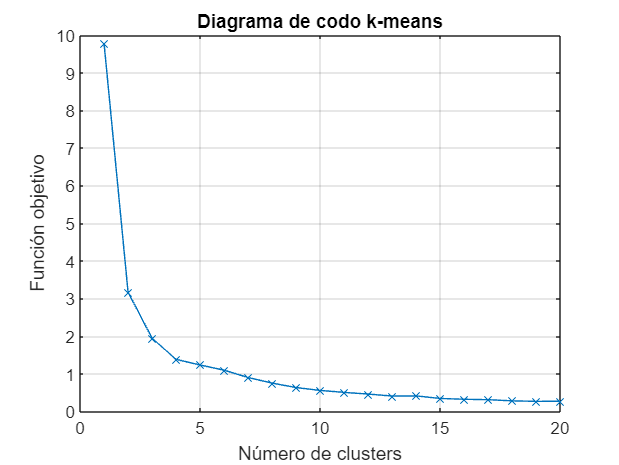

rng(0);

% Diagrama de codo
for i =1:n
    [idx, C, SumD] = kmeans(X,i);
    Jkm(i) = sum(SumD);
    Kkm(i) = i;
end

figure;
plot(Kkm, Jkm,"-x");
grid on;
xlabel("Número de clusters");
ylabel("Función objetivo");
title("Diagrama de codo k-means");

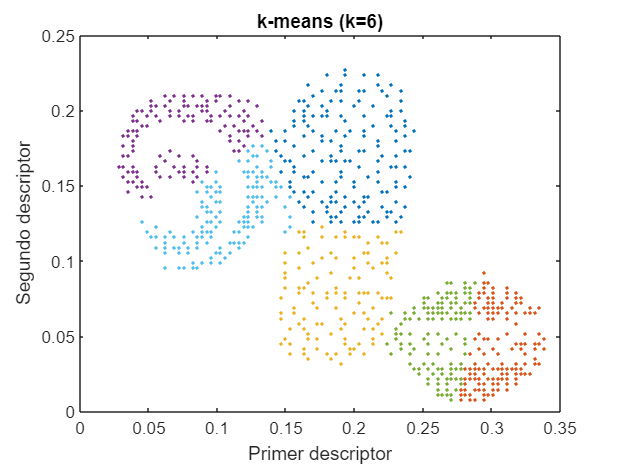


% Clustering
idx = kmeans(X,k);

% Visualización de datos
figure;
for i=1:max(idx)
    plot(X(idx==i,1),X(idx==i,2),".","MarkerFaceColor",[rand(1,1) rand(1,1) rand(1,1)])
    hold on;
end
xlabel("Primer descriptor");
ylabel("Segundo descriptor");
title(strcat("k-means (k=",string(k),")"));


% Métricas
fprintf("Valores de métricas k-means")

Valores de métricas k-means

[SSW,SSB,WB,SIL]=MetricasNoSupervisado(X,idx)

SSW = 0.0307

SSB = 0.0922

WB = 1.9949

SIL = 0.5302



% ---------------------------------------
% k-medoids
% ---------------------------------------
fprintf("---------------------------------------")

---------------------------------------

fprintf("k-medoids")

k-medoids

fprintf("---------------------------------------")

---------------------------------------


n = 20

n = 20

k = 6

k = 6

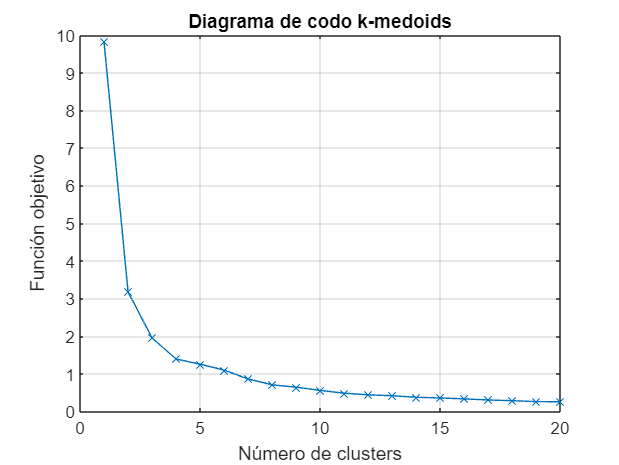

rng(0);

% Diagrama de codo
for i =1:n
    [idx, C, SumD] = kmedoids(X,i);
    Jkmd(i) = sum(SumD);
    Kkmd(i) = i;
end

figure;
plot(Kkmd, Jkmd,"-x");
grid on;
xlabel("Número de clusters");
ylabel("Función objetivo");
title("Diagrama de codo k-medoids");

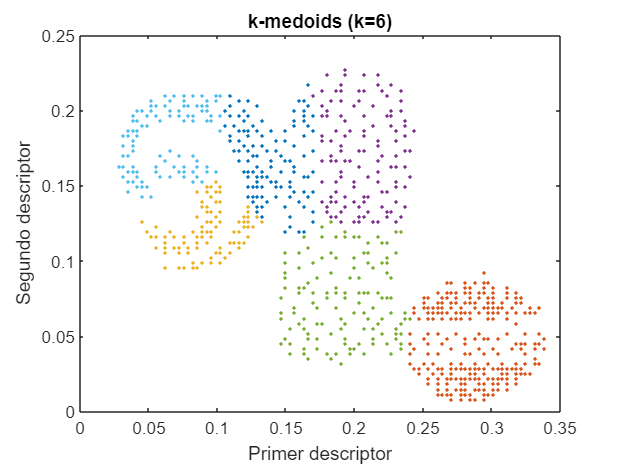


% Clustering
idx = kmedoids(X,k);

% Visualización de datos
figure;
for i=1:max(idx)
    plot(X(idx==i,1),X(idx==i,2),".","MarkerFaceColor",[rand(1,1) rand(1,1) rand(1,1)])
    hold on;
end
xlabel("Primer descriptor");
ylabel("Segundo descriptor");
title(strcat("k-medoids (k=",string(k),")"));


% Métricas
fprintf("Valores de métricas k-medoids")

Valores de métricas k-medoids

[SSW,SSB,WB,SIL]=MetricasNoSupervisado(X,idx)

SSW = 0.0308

SSB = 0.0927

WB = 1.9896

SIL = 0.6343


% ---------------------------------------
% DBSCAN
% ---------------------------------------
fprintf("---------------------------------------")

---------------------------------------

fprintf("DBSCAN")

DBSCAN

fprintf("---------------------------------------")

---------------------------------------

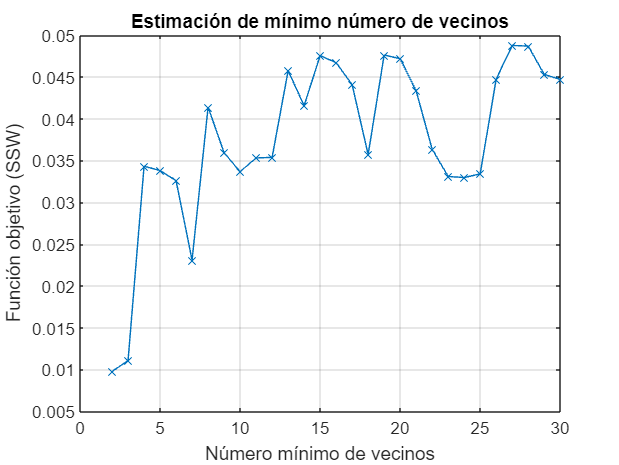


min_n = 12;
gmin_n = 2:1:30;

% Estimación número mínimo de vecinos
for i = 1:length(gmin_n)
    rng(0);
    min_ng = gmin_n(i);
    ep = clusterDBSCAN.estimateEpsilon(X,min_ng,min_ng);
    idx = dbscan(X,ep,min_ng);
    [SSWdb(i) SSBdb(i) WBdb(i) SILdb(i)] = MetricasNoSupervisado(X(idx>0,:),idx(idx>0));
    Kdb(i)=min_ng;
end

figure;
plot(Kdb,SSWdb,"-x");
grid on;
xlabel("Número mínimo de vecinos");
ylabel("Función objetivo (SSW)");
title("Estimación de mínimo número de vecinos");

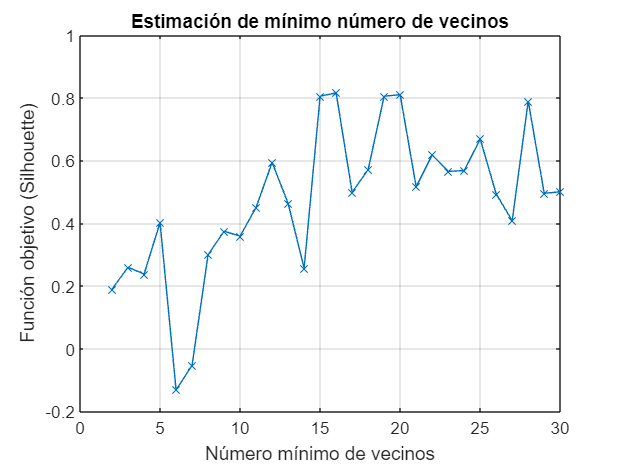


figure;
plot(Kdb,SILdb,"-x");
grid on;
xlabel("Número mínimo de vecinos");
ylabel("Función objetivo (Silhouette)");
title("Estimación de mínimo número de vecinos");



% Gráfica k-NN (Nearest Neigbor)
min_n

min_n = 12

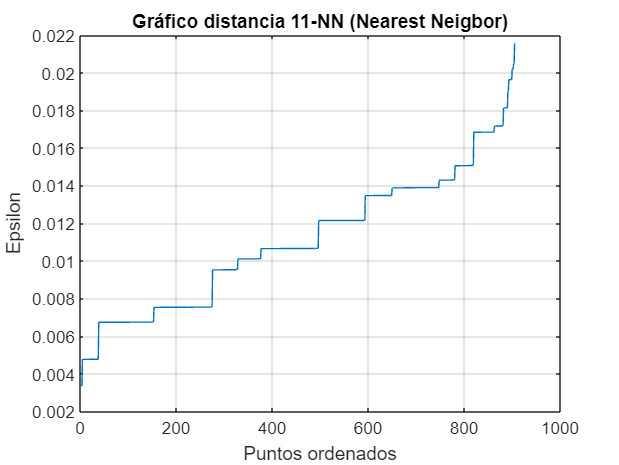

figure;
kD = pdist2(X,X,'euc','Smallest',min_n-1);
plot(sort(kD(end,:)));
title(strcat("Gráfico distancia ",string(min_n-1),"-NN (Nearest Neigbor)"));
xlabel("Puntos ordenados");
ylabel("Epsilon");
grid;


% Clustering
rng(0);
ep = clusterDBSCAN.estimateEpsilon(X,min_n,min_n)

ep = 0.0122

idx = dbscan(X,ep,min_n);
clusters = unique(idx(idx>0));
num_clusters = length(clusters)

num_clusters = 5

anomalias = length(idx(idx<=0));

if (anomalias>0)
    fprintf(strcat("Existen ",string(anomalias)," anomalías"));
else
    fprintf("No existen anomalías");
end

Existen 182 anomalías

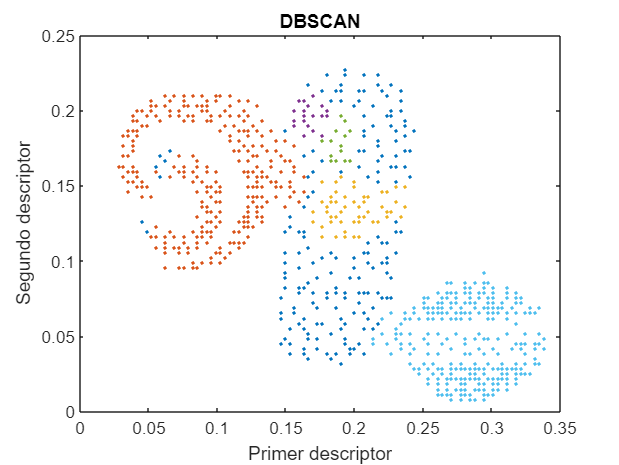


% Visualización de datos
figure;
for i=min(idx):max(idx)
    plot(X(idx==i,1),X(idx==i,2),".","MarkerFaceColor",[rand(1,1) rand(1,1) rand(1,1)])
    hold on;
end
xlabel("Primer descriptor");
ylabel("Segundo descriptor");
title(strcat("DBSCAN"));


% Métricas
fprintf("Valores de métricas DBSCAN")

Valores de métricas DBSCAN

[SSW,SSB,WB,SIL]=MetricasNoSupervisado(X(idx>0,:),idx(idx>0))

SSW = 0.0354

SSB = 0.1014

WB = 1.7432

SIL = 0.5936


% ---------------------------------------
% Clustering Jerárquico
% ---------------------------------------
fprintf("---------------------------------------")

---------------------------------------

fprintf("Clustering Jerárquico")

Clustering Jerárquico

fprintf("---------------------------------------")

---------------------------------------


n = 20

n = 20

k = 6

k = 6

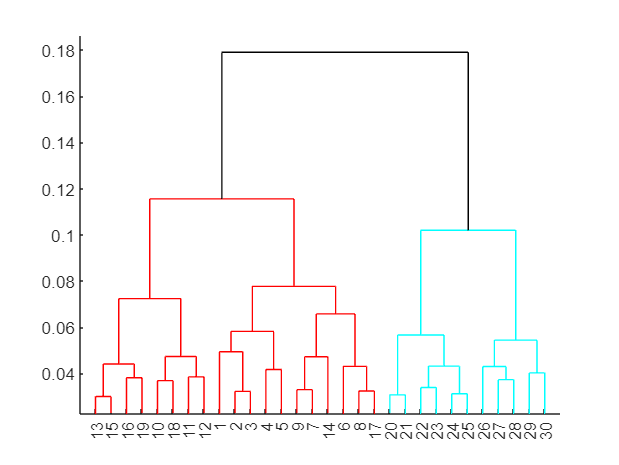

rng(0);

% Dendrograma
tree = linkage(X,"average","euclidean");
figure;
dendrogram(tree,"ColorThreshold","default")

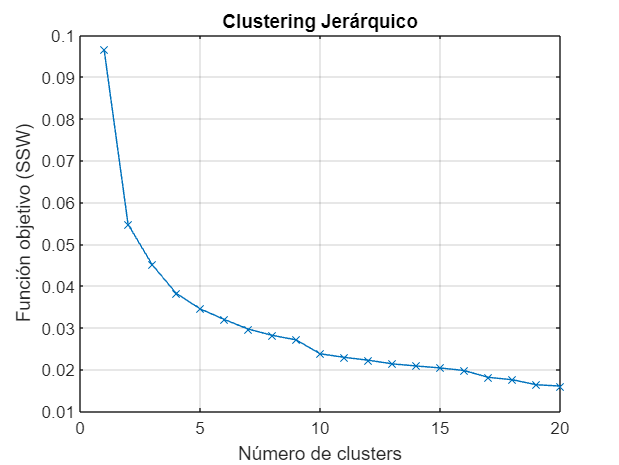


% Diagrama de codo
for i =1:n
    idx = cluster(tree,"maxclust",i);
    [SSWhc(i) SSBhc(i) WBhc(i) SILhc(i)] = MetricasNoSupervisado(X,idx);
    Khc(i)=i;
end

figure;
plot(Khc,SSWhc,"-x");
grid on;
xlabel("Número de clusters");
ylabel("Función objetivo (SSW)");
title("Clustering Jerárquico");

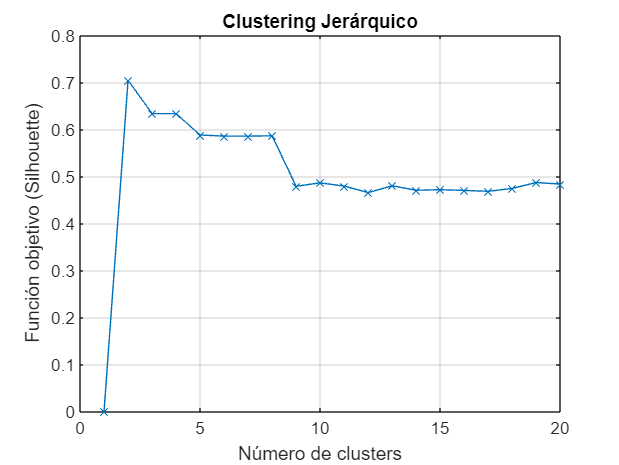


figure;
plot(Khc,SILhc,"-x");
grid on;
xlabel("Número de clusters");
ylabel("Función objetivo (Silhouette)");
title("Clustering Jerárquico");

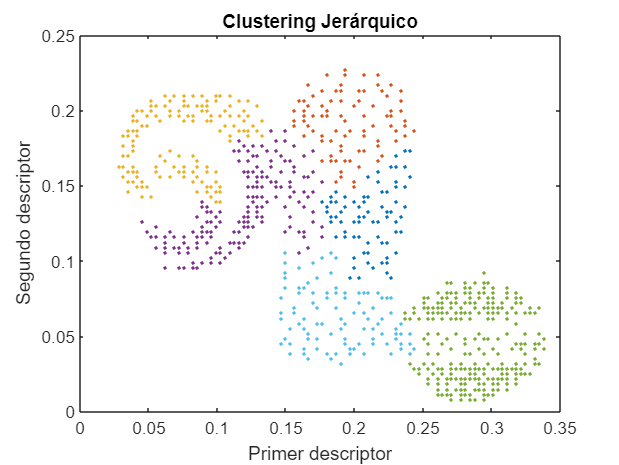


% Clusterización
idx = cluster(tree,"maxclust",k);

% Visualización de datos
figure;
for i=1:max(idx)
    plot(X(idx==i,1),X(idx==i,2),".","MarkerFaceColor",[rand(1,1) rand(1,1) rand(1,1)])
    hold on;
end
xlabel("Primer descriptor");
ylabel("Segundo descriptor");
title("Clustering Jerárquico");


% Métricas
fprintf("Valores de métricas Clustering Jerárquico")

Valores de métricas Clustering Jerárquico

[SSW,SSB,WB,SIL]=MetricasNoSupervisado(X,idx)

SSW = 0.0320

SSB = 0.0924

WB = 2.0761

SIL = 0.5851


% ---------------------------------------
% Fuzzy c-means
% ---------------------------------------
fprintf("---------------------------------------")

---------------------------------------

fprintf("Fuzzy c-means")

Fuzzy c-means

fprintf("---------------------------------------")

---------------------------------------


n=20

n = 20

c=6

c = 6

rng(0);

% Diagrama de codo
for i =1:n
    [centers,U] = fcm(X,i);
    Ut=U';
    idx= ones(length(Ut),1);
    maxU = max(U)';

    for j = 1:i
        s = Ut(:,j);
        f = find(s==maxU);
        idx(f)=j;
    end

    [SSWfcm(i) SSBfcm(i) WBfcm(i) SILfcm(i)] = MetricasNoSupervisado(X,idx);
    Kfcm(i)=i;
end

Iteration count = 1, obj. fcn = 0.000016
Iteration count = 2, obj. fcn = 0.000003
Iteration count = 3, obj. fcn = 0.000001
Minimum improvement reached.
Iteration count = 1, obj. fcn = 5.944723
Iteration count = 2, obj. fcn = 4.882869
Iteration count = 3, obj. fcn = 4.813299
Iteration count = 4, obj. fcn = 4.330303
Iteration count = 5, obj. fcn = 3.032929
Iteration count = 6, obj. fcn = 2.519566
Iteration count = 7, obj. fcn = 2.494545
Iteration count = 8, obj. fcn = 2.493987
Iteration count = 9, obj. fcn = 2.493972
Iteration count = 10, obj. fcn = 2.493972
Minimum improvement reached.
Iteration count = 1, obj. fcn = 4.153311
Iteration count = 2, obj. fcn = 3.237755
Iteration count = 3, obj. fcn = 3.080701
Iteration count = 4, obj. fcn = 2.455834
Iteration count = 5, obj. fcn = 1.845409
Iteration count = 6, obj. fcn = 1.621156
Iteration count = 7, obj. fcn = 1.498045
Iteration count = 8, obj. fcn = 1.446821
Iteration count = 9, obj. fcn = 1.419353
Iteration count = 10, obj. fcn = 1.4023

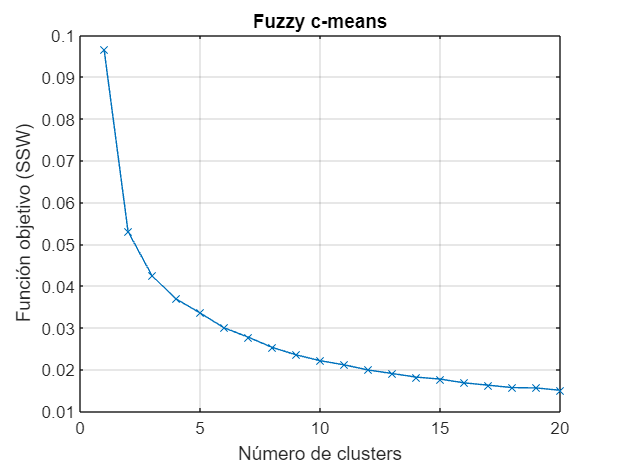


figure;
plot(Kfcm,SSWfcm,"-x");
grid on;
xlabel("Número de clusters");
ylabel("Función objetivo (SSW)");
title("Fuzzy c-means");


% Clusterización
[centers,U] = fcm(X,c);

Iteration count = 1, obj. fcn = 2.183206
Iteration count = 2, obj. fcn = 1.624437
Iteration count = 3, obj. fcn = 1.579456
Iteration count = 4, obj. fcn = 1.337151
Iteration count = 5, obj. fcn = 0.927352
Iteration count = 6, obj. fcn = 0.742556
Iteration count = 7, obj. fcn = 0.663980
Iteration count = 8, obj. fcn = 0.621956
Iteration count = 9, obj. fcn = 0.596953
Iteration count = 10, obj. fcn = 0.582606
Iteration count = 11, obj. fcn = 0.575157
Iteration count = 12, obj. fcn = 0.571421
Iteration count = 13, obj. fcn = 0.569383
Iteration count = 14, obj. fcn = 0.568087
Iteration count = 15, obj. fcn = 0.567144
Iteration count = 16, obj. fcn = 0.566399
Iteration count = 17, obj. fcn = 0.565786
Iteration count = 18, obj. fcn = 0.565274
Iteration count = 19, obj. fcn = 0.564844
Iteration count = 20, obj. fcn = 0.564482
Iteration count = 21, obj. fcn = 0.564180
Iteration count = 22, obj. fcn = 0.563929
Iteration count = 23, obj. fcn = 0.563720
Iteration count = 24, obj. fcn = 0.563547
I

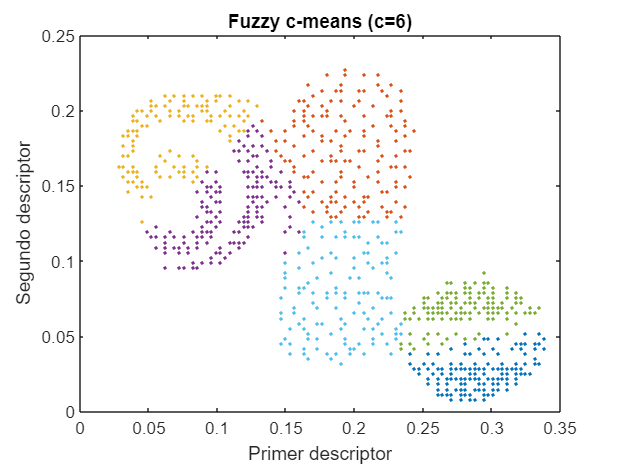

Ut=U';
idx= ones(length(Ut),1);
maxU = max(U)';

for i = 1:c
    s = Ut(:,i);
    f = find(s==maxU);
    idx(f)=i;
end

% Visualización de datos
figure;
for i=1:max(idx)
    plot(X(idx==i,1),X(idx==i,2),".","MarkerFaceColor",[rand(1,1) rand(1,1) rand(1,1)])
    hold on;
end
xlabel("Primer descriptor");
ylabel("Segundo descriptor");
title(strcat("Fuzzy c-means (c=",string(c),")"));


% Métricas
fprintf("Valores de métricas Fuzzy c-means")

Valores de métricas Fuzzy c-means

[SSW,SSB,WB,SIL]=MetricasNoSupervisado(X,idx)

SSW = 0.0299

SSB = 0.0920

WB = 1.9534

SIL = 0.5564


toc

Elapsed time is 9.800385 seconds.
